# **插值**

**分段线性插值**

$\mathrm{F1}=\frac{x-x_{i+1} }{x_i -x_{i-1} }$f($x_i$)+$\frac{x-x_i }{x_{i+1} -x_i }$f($x_{i+1}$)

这里使用到自定义线性插值函数，具体函数使用详见函数开头介绍，liner.m

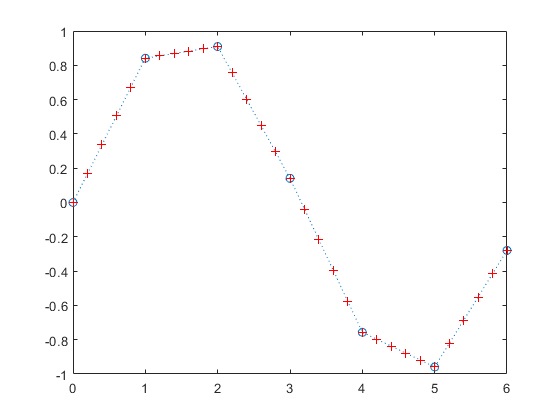

clear
x=0:2*pi;
y=sin(x);
xx=0:0.2:6;
yy=liner(x,y,xx);
plot(x,y,'o:',xx,yy,'+r');%圆圈给出的点是已给的点，其他点是采用线性插值得到的补充值

**拉格朗日插值**

**拉格朗日插值多项式**

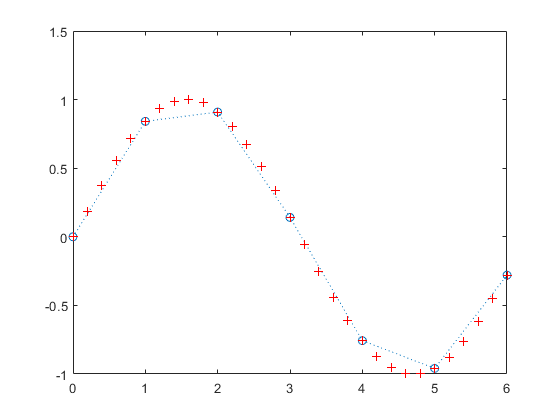

x=0:2*pi;
y=sin(x);
xx=0:0.2:6;
yy=lagrange(x,y,xx);
plot(x,y,'o:',xx,yy,'+r')%圆圈给出的点是已给的点，其他点是采用线性插值得到的补充值

**利用系统函数实现一维插值**

yi=interp1(x，y，xi，'method')

‘nearest’：最邻近插值     ‘linear’： 线性插值；

‘spline’： 三次样条插值； ‘cubic’： 立方插值。

缺省时：  分段线性插值。

**线性插值**

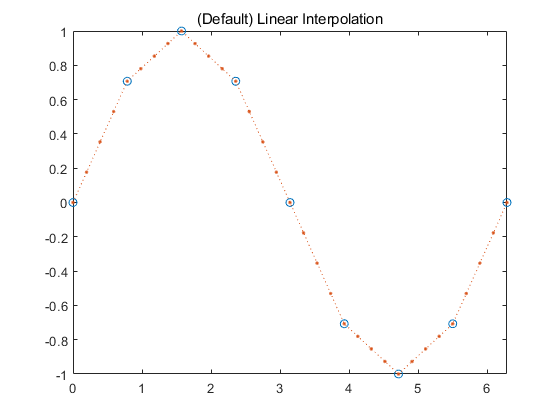

%线性插值
x = 0:pi/4:2*pi; 
v = sin(x);
xq = 0:pi/16:2*pi;
figure
vq1 = interp1(x,v,xq);
plot(x,v,'o',xq,vq1,':.');
xlim([0 2*pi]);
title('(Default) Linear Interpolation');

**三次样条插值**

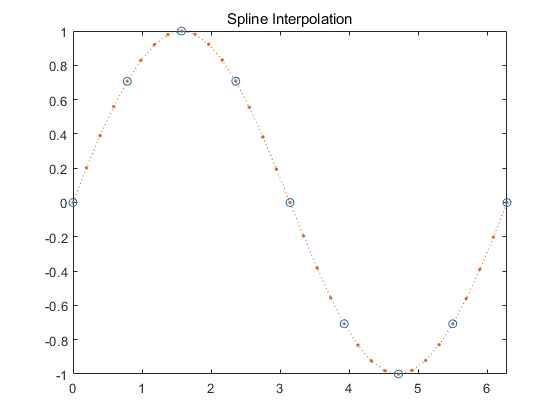

figure
vq2 = interp1(x,v,xq,'spline');
plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Spline Interpolation');

**二维插值interp2**

`z=interp2(x0,y0,z0,x,y,’method’)`

**‘**`nearest`**’**   **最邻近插值**

**‘**`linear`**’**   **双线性插值**

**‘**`cubic`**’**    **双三次插值**

**缺省时****,**  **双线性插值**

**双线性插值**

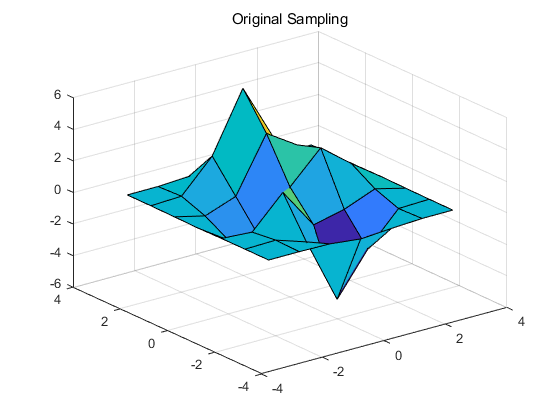

[X,Y] = meshgrid(-3:3);
V = peaks(X,Y);
figure
surf(X,Y,V)
title('Original Sampling');

**双三次插值**

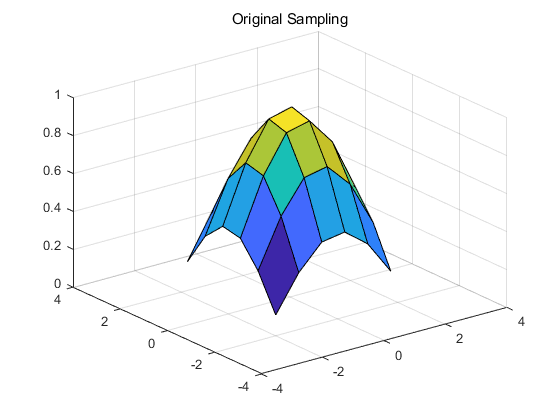

[X,Y] = meshgrid(-2:0.75:2);
R = sqrt(X.^2 + Y.^2)+ eps;
V = sin(R)./(R);
figure
surf(X,Y,V)
xlim([-4 4])
ylim([-4 4])
title('Original Sampling')

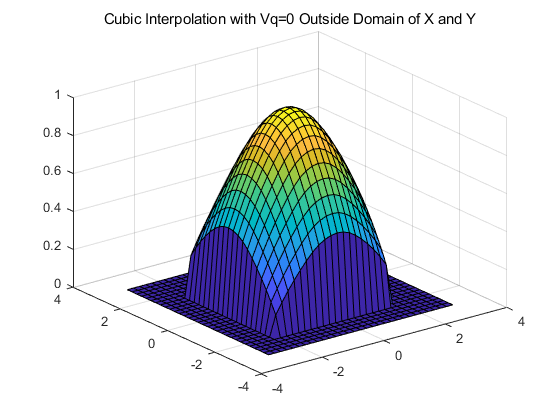

[Xq,Yq] = meshgrid(-3:0.2:3);%利用插值扩展图形
Vq = interp2(X,Y,V,Xq,Yq,'cubic',0);
figure
surf(Xq,Yq,Vq)
title('Cubic Interpolation with Vq=0 Outside Domain of X and Y');%Vq = interp2(___,method,extrapval)区域外赋值为0

**griddata函数**

**cz =griddata**`（`**x**`，`**y**`，`**z**`，`**cx**`，`**cy**`，‘`**method’**`）`

`这个函数用来获取插值结果的散点。根据给定的x,y值给出z的值。观察具体二维插值的插值点，此处不再赘述。`

# `拟合`

`注意拟合只适用于插值区间缺少数据的情况，对于插值区间外的数据不具有预测性`

`线性最小二乘拟合（多项式拟合）(polyfit)`

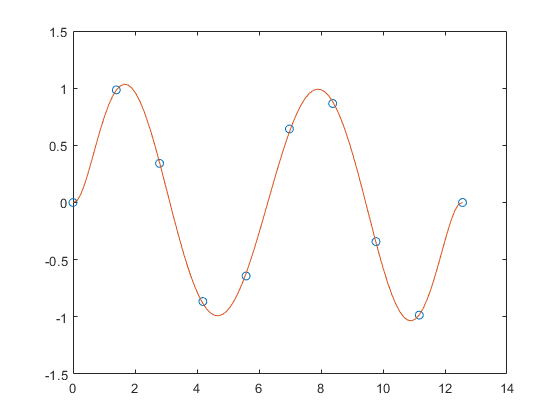

x = linspace(0,4*pi,10);
y = sin(x);
p = polyfit(x,y,7);%生成多项式
x1 = linspace(0,4*pi);
y1 = polyval(p,x1);
figure
plot(x,y,'o')%拟合前
hold on
plot(x1,y1)%拟合后
hold off

x=0:0.1:1;
y=[-0.447 1.978 3.28 6.16 7.08 7.34 7.66 9.56 9.48 9.30 11.2];
A=polyfit(x,y,2)

A =    -9.8108   20.1293   -0.0317


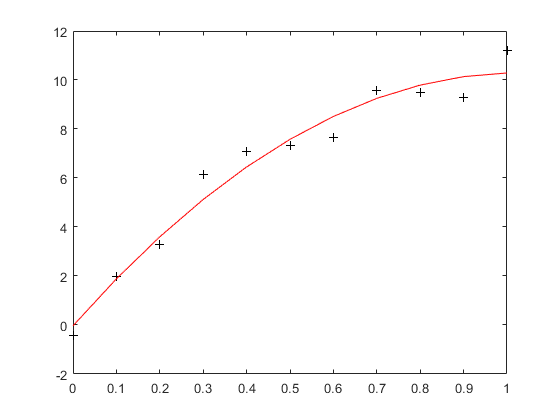

z=polyval(A,x);
plot(x,y,'k+',x,z,'r')      %作出数据点和拟合曲线的图形

**非线性最小二乘拟合**

tdata=100:100:1000

tdata =          100         200         300         400         500         600         700         800         900        1000


cdata=1e-03*[4.54,4.99,5.35,5.65,5.90,6.10,6.26,6.39,6.50,6.59];
 x0=[0.2,0.05,0.05];
 x=lsqcurvefit ('curvefun1',x0,tdata,cdata)

f =     0.2452    0.2409    0.2370    0.2335    0.2303    0.2274    0.2248    0.2225    0.2203    0.2184


f =     0.2452    0.2409    0.2370    0.2335    0.2303    0.2274    0.2248    0.2225    0.2203    0.2184


f =     0.2452    0.2409    0.2370    0.2335    0.2303    0.2274    0.2248    0.2225    0.2203    0.2184


f =     0.2452    0.2409    0.2370    0.2335    0.2303    0.2274    0.2248    0.2225    0.2203    0.2184


f =     0.0042    0.0043    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0051


f =     0.0042    0.0043    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0051


f =     0.0042    0.0043    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0051


f =     0.0042    0.0043    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0051


f =     0.0044    0.0047    0.0049    0.0051    0.0052    0.0053    0.0053    0.0054    0.0054    0.0054


f =     0.0044    0.0047    0.0049    0.0051    0.0052    0.0053    0.0053    0.0054    0.0054    0.0054


f =     0.0044    0.0047    0.0049    0.0051    0.0052    0.0053    0.0053    0.0054    0.0054    0.0054


f =     0.0044    0.0047    0.0049    0.0051    0.0052    0.0053    0.0053    0.0054    0.0054    0.0054


f =     0.0042    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054


f =     0.0042    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054


f =     0.0042    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054


f =     0.0042    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054


f =     0.0050    0.0053    0.0055    0.0057    0.0059    0.0060    0.0060    0.0061    0.0062    0.0062


f =     0.0050    0.0053    0.0055    0.0057    0.0059    0.0060    0.0060    0.0061    0.0062    0.0062


f =     0.0050    0.0053    0.0055    0.0057    0.0059    0.0060    0.0060    0.0061    0.0062    0.0062


f =     0.0050    0.0053    0.0055    0.0057    0.0059    0.0060    0.0060    0.0061    0.0062    0.0062


f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064


f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064


f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064


f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     0.0069   -0.0029    0.0809


 f= curvefun1(x,tdata) 

f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064


f =     0.0044    0.0048    0.0051    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0064


**lsqnonlin函数**

 x0=[0.2,0.05,0.05];
x=lsqnonlin('curvefun2',x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     0.0069   -0.0029    0.0809


f= curvefun2(x)

f = 	1.0e+-3 *

   -0.0971   -0.1739   -0.2164   -0.2463   -0.2666   -0.2713   -0.2651   -0.2538   -0.2436   -0.2313
